# Final Project

## Paul Keene, Erica Lin

Dataset: Steinmetz, Zatka-Haas, Carandini & Harris 2019

## Setup

%set project directory (will need to change on different machine)
projDir = pwd;

%get session IDs and number
[sessionNames,nsesh] = getSessionNames(projDir);

%load the data from the raw files
[beh,eye] = loadData(sessionNames,nsesh,projDir);
load('sorted_data/neural/MOpspikes.mat'); %we used the preprocessing scripts indexClusters and selectClusters to make this


% load paths for functions
visualization_path = [pwd,'/visualize']; 
addpath(visualization_path);
analysis_path = [pwd,'/analysis']; 
addpath(analysis_path);
helper_path = [pwd,'/helpers'];
addpath(helper_path);
%Paul = 100%

## Visualization

% motor neuron activity during response to left vs right vs neutral trials
%raster_subject1_directional(beh, spikes)
%Erica = 100%

VISp neuron activity during stimulus of high, medium, and no difference between right and left:

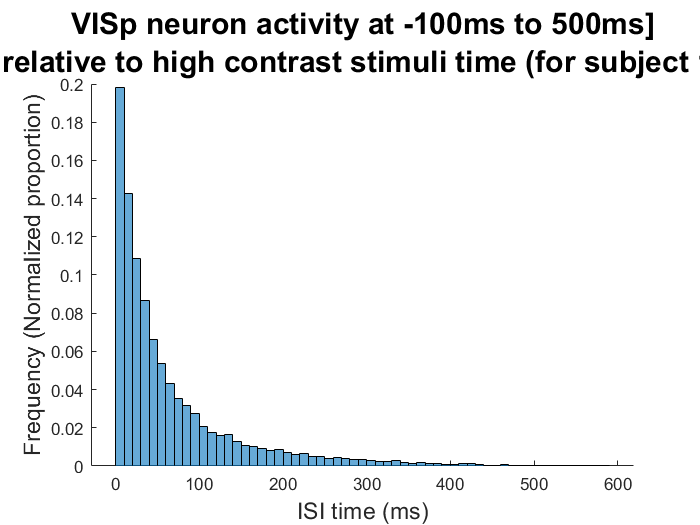

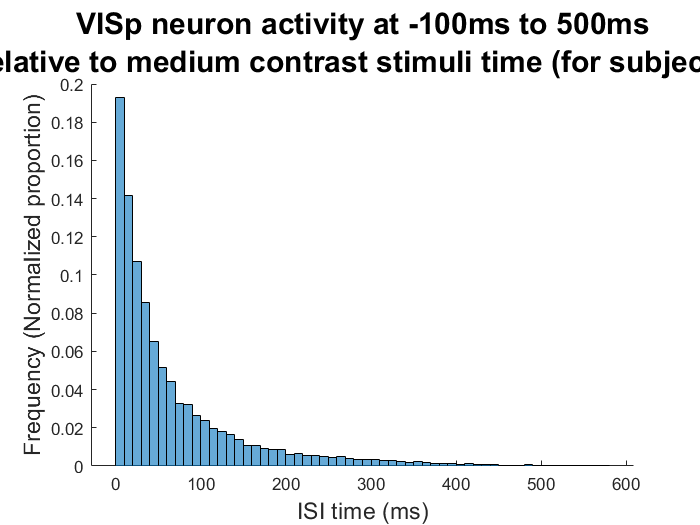

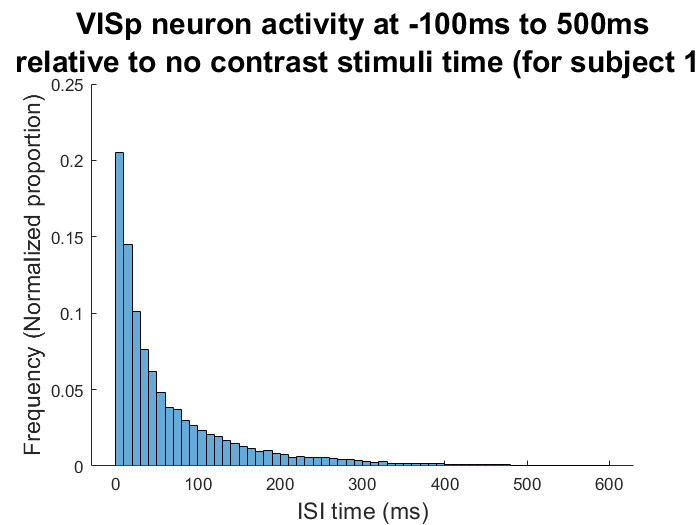

The ISI for high and medium differences between left/right are very similar. When there is no difference between left/right, there are relatively more interspike intervals on the shorter side -- there is more frequent spiking of the visual neuron when there is no difference between left/right.

% visual neuron activity during stimulus of high, medium, and no difference between right and left
isi_subject1_contrast(beh, spikes)

%Erica = 100%

PSTH for average spike counts during stimulus times for motor and and visual neurons. CI's shown by red and yellow edges.

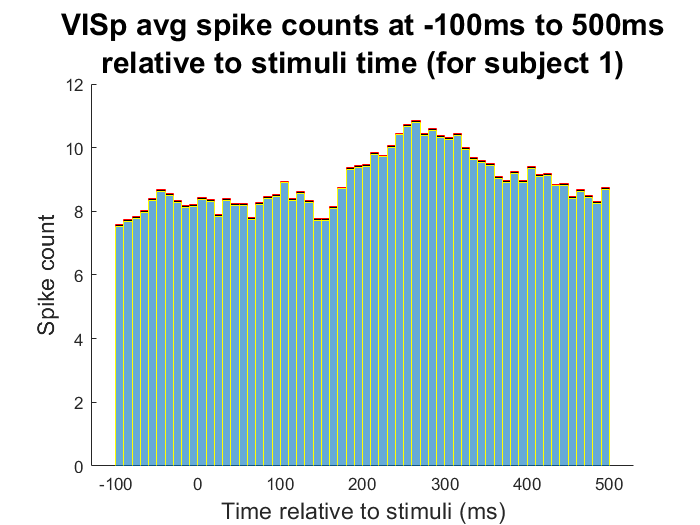

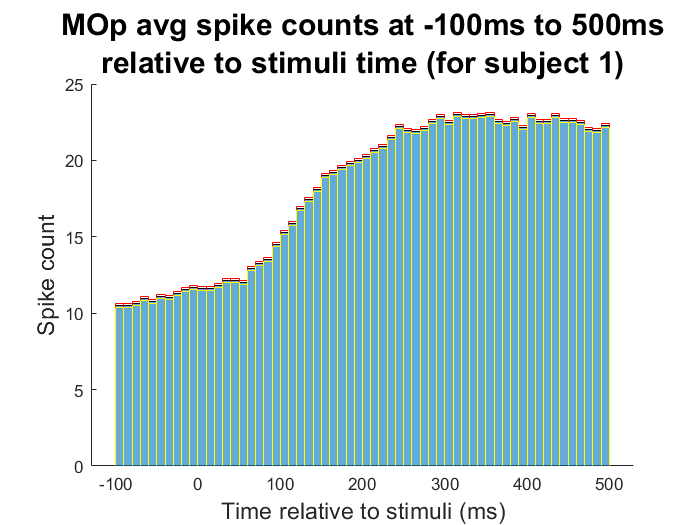

Overall, there is higher spike count for the visual neurons compared to the motor neurons. The motor neurons peak slightly before the visual neurons.

% average spike counts during stimulus times for motor and visual neurons
psth_avg_spike_count(beh, spikes)

%Erica = 80, Paul = 20%

% visualize gaze after stimulus appears
gaze_tracking() 
print('gaze_track','-dpng');
%Paul = 100%

% visualize wheel position during trial
wheel_position()
print('wheelpos','-dpng');
%Paul = 100%

%histogram of accuracy sorted by delay interval
accuracy_v_delay()
print('acc_delay','-dpng');
%Paul = 100%

## Analysis

% Spike train variability for MOs 50ms 
% before / after 
% stimulus / go cue / response
spike_train_variability(beh, spikes)

Find the Fano Factor of 50 ms before audio go-cue, 50 ms after audio go-cue, 50 ms before visual go-cue, and 50 ms after visual go-cue.MOs Fano Factor for spike count 50 ms before stimulus

ans = 128.4565

p = 0.4980

MOs Fano Factor for spike count 50 ms after stimulus

ans = 125.8318

p = 0.4944

MOs Fano Factor for spike count 50 ms before go cue

ans = 135.8104

p = 0.5040

MOs Fano Factor for spike count 50 ms after go cue

ans = 134.3626

p = 0.4992

MOs Fano Factor for spike count 50 ms before response

ans = 128.6591

p = 0.4949

MOs Fano Factor for spike count 50 ms after response

ans = 130.1662

p = 0.4943

Fano Factor of spike count in MOs is always higher (relatively higher spike count variability)after stimulus / go cue / response than before.
Fano Factor of spike count in MOs is lowest overall after response -- there is relatively lower spike count variability after response.

%Erica = 90% Paul = 10%

% Encoder for response time on MOs spike rates
encoding_response_time(beh, spikes)

Linear regression for response time on MOs spike rate 50 ms before audio go-cue, 50 ms after stimulus 50 ms before visual go-cue, and 50 ms after go-cue 50 ms before response, and 50 ms after response.

model_coeffs = 7×4 table
                    Estimate          SE          tStat        pValue   
                   ___________    __________    _________    ___________

    (Intercept)          2.824      0.087901       32.127    2.4795e-104
    x1               3.855e-06    6.7701e-05     0.056941        0.95463
    x2             -9.5203e-06    5.7773e-05     -0.16479        0.86921
    x3             -0.00026105     3.617e-05      -7.2173     3.5762e-12
    x4             -2.7394e-06     4.116e-05    -0.066556        0.94697
    x5              -0.0002676    4.5511e-05      -5.8799      9.932e-09
    x6             -3.4029e-05    4.6948e-05     -0.72482        0.46907


model_summary = 3×5 table
                SumSq     DF     MeanSq       F         pValue  
                ______    ___    _______    ______    __________

    Total        131.6    341    0.38593                        
    Model       87.477      6      14.58    110.69    2.0512e-76
    Residual    44.126    335    0.13172                        


The model has quite a low p-value (0.02).The coefficients all have a high p-value, except for that of the spike rate of MOs prior to response (p = 0.005).The coefficient for spike rate prior to response is -0.0013, which tells us that a higher MOs spike rate prior to response corresponds very slightly to a lower response time.

%Erica = 100%

% Classifiers for response speed on MOs spike counts during response
classify_response_speed(beh, spikes)

Classify reaction speeds as fast (< 1 sec) or slow (> 2 sec)


glm_percentage_classified_correctly = 84.21%


lasso_percentage_classified_correctly = 91.10%
svm_percentage_classified_correctly = 88.67%
Classification percentage for all 3 models were quite low, between approximately 60-68

%Erica = 100%

%linearly reduce dimensionality
load('sorted_data/neural/MOpspike_pca.mat');
condSpikeCounts = prepDimReduct(beh,spikes);
dimensionalityReduction(condSpikeCounts);

reduce dimensionality and examine what low d state best captures the activity of the neurons in MOs

error grows with more dimensions. It may be the secondary motor area isnt very modulated in this task

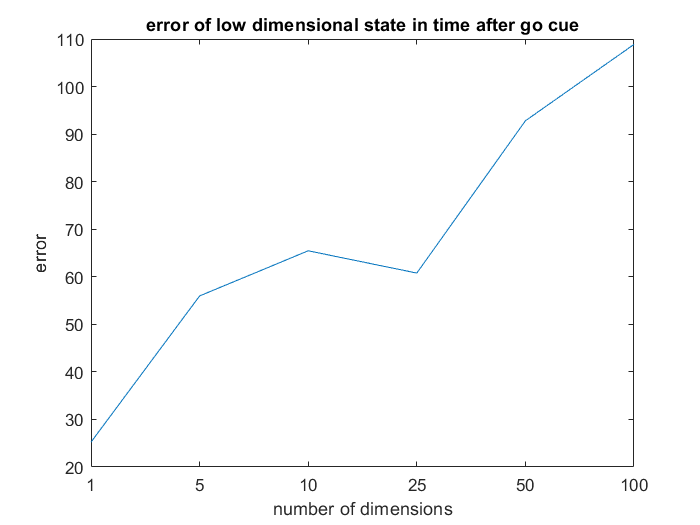

print('dim reduct','-dpng');

load('sorted_data/neural/MOpspikes.mat');
%Paul = 100%

%train auto encoder
%%%%%%% WIP %%%%%%%%%
%(Paul's taking point)